%% problem 2.4 
syms('a','positive','real')
syms('n','positive','integer')

syms('x','real')
psi_n(x)= sqrt(2/a)*sin( (n*pi /a) *x)

$$psi\_n(x) = \frac{\sqrt{2}\,\sin\left(\frac{\pi \,n\,x}{a}\right)}{\sqrt{a}}$$

exp_x=int(psi_n*x*psi_n,x,0,a)

$$exp\_x = \frac{a}{2}+\frac{2\,a\,\left(\frac{{\sin\left(\pi \,n\right)}^{2}}{4}-\frac{\pi \,n\,\sin\left(2\,\pi \,n\right)}{4}\right)}{n^{2}\,\pi^{2}}$$


exp_x2=int(psi_n*(x^2)*psi_n,x,0,a)

$$exp\_x2 = \frac{a^{2}\,\left(3\,\sin\left(2\,\pi \,n\right)+4\,n^{3}\,\pi^{3}-6\,n^{2}\,\pi^{2}\,\sin\left(2\,\pi \,n\right)-6\,\pi \,n\,\cos\left(2\,\pi \,n\right)\right)}{12\,n^{3}\,\pi^{3}}$$

syms('h',"positive","real")
exp_p=int(psi_n*(h/i)*diff(psi_n,x),x,0,a)

$$exp\_p = -\frac{h\,{\sin\left(\pi \,n\right)}^{2}\,\mathrm{i}}{a}$$


exp_p2=int(psi_n*(h/i)^2*diff(psi_n,x,2),x,0,a)

$$exp\_p2 = -\frac{h^{2}\,n^{2}\,\pi^{2}\,\left(\frac{\sin\left(2\,\pi \,n\right)}{2\,n\,\pi }-1\right)}{a^{2}}$$


sigma_x = sqrt(simplify(exp_x2 - exp_x^2))

$$sigma\_x = \frac{a\,\sqrt{\frac{n^{2}\,\pi^{2}}{12}-\frac{1}{2}}}{n\,\pi }$$


sigma_p= sqrt(simplify(exp_p2 - exp_p*conj(exp_p)))

$$sigma\_p = \frac{\pi \,h\,n}{a}$$

uncertainty=sigma_x*sigma_p

$$uncertainty = h\,\sqrt{\frac{n^{2}\,\pi^{2}}{12}-\frac{1}{2}}$$

ratio = simplify(uncertainty/(h/2))      

$$ratio = \frac{\sqrt{3}\,\sqrt{n^{2}\,\pi^{2}-6}}{3}$$

vpa(subs(ratio, n, 1:5))

$$ans = \left(\begin{array}{ccccc} 1.1357236167732239567812927498161 & 3.3405796704742444282962443993138 & 5.2544089299623488532421909718755 & 7.116030504371327241220283097637 & 8.9580524302111182622078149307987 \end{array}\right)$$


%The ground state (n=1) satisfies the uncertainty principle
%and is the closest to the limit (a ratio below 1 would mean it didn't
%satisfy)

clear
clc
%% problem 2.5
syms('a','positive','real')
syms('n','positive','integer')
syms('h',"positive","real")
syms('x','real')
psi_n(x)= sqrt(2/a)*sin( (n*pi /a) *x)

$$psi\_n(x) = \frac{\sqrt{2}\,\sin\left(\frac{\pi \,n\,x}{a}\right)}{\sqrt{a}}$$


psi1=subs(psi_n,n,1)

$$psi1(x) = \frac{\sqrt{2}\,\sin\left(\frac{\pi \,x}{a}\right)}{\sqrt{a}}$$

psi2=subs(psi_n,n,2)

$$psi2(x) = \frac{\sqrt{2}\,\sin\left(\frac{2\,\pi \,x}{a}\right)}{\sqrt{a}}$$

syms('A','positive','real')
PSI(x)=A*(psi1 + psi2)

$$PSI(x) = A\,\left(\frac{\sqrt{2}\,\sin\left(\frac{\pi \,x}{a}\right)}{\sqrt{a}}+\frac{\sqrt{2}\,\sin\left(\frac{2\,\pi \,x}{a}\right)}{\sqrt{a}}\right)$$

A= solve(int(PSI^2,x,0,a)==1,A)

$$A = \frac{\sqrt{2}}{2}$$

PSI(x)=simplify(subs(PSI(x)))

$$PSI(x) = \frac{\sin\left(\frac{\pi \,x}{a}\right)+\sin\left(\frac{2\,\pi \,x}{a}\right)}{\sqrt{a}}$$

%syms('m','positive','real')

syms('omega','positive','real')
E1= h*omega

$$E1 = h\,\omega$$

E2=E1*4

$$E2 = 4\,h\,\omega$$

syms('t','positive','real')
Psi(x,t)=simplify(A*(psi1*exp(-i*E1*t/h) + psi2*exp(-i*E2*t/h) ))

$$Psi(x, t) = \frac{\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{-4\,\omega \,t\,\mathrm{i}}}{\sqrt{a}}$$

Psi2=simplify( Psi(x,t)*conj(Psi(x,t)))

$$Psi2 = \frac{\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{-4\,\omega \,t\,\mathrm{i}}\right)\,\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{4\,\omega \,t\,\mathrm{i}}\right)}{a}$$

a_num=1;
omega_num=1;
%Psi2_plot=subs(Psi2(x,t));
t_plot=linspace(0,5,50)

t_plot =          0    0.1020    0.2041    0.3061    0.4082    0.5102    0.6122    0.7143    0.8163    0.9184    1.0204    1.1224    1.2245    1.3265    1.4286    1.5306    1.6327    1.7347    1.8367    1.9388    2.0408    2.1429    2.2449    2.3469    2.4490    2.5510    2.6531    2.7551    2.8571    2.9592    3.0612    3.1633    3.2653    3.3673    3.4694    3.5714    3.6735    3.7755    3.8776    3.9796    4.0816    4.1837    4.2857    4.3878    4.4898    4.5918    4.6939    4.7959    4.8980    5.0000


x_plot=linspace(0,1,50)

x_plot =          0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1.0000


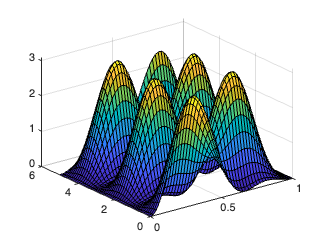

[X,T]=meshgrid(x_plot,t_plot);
Psi2_plot=(double(subs(Psi2, {x, t, a, omega}, {X, T, a_num, omega_num})));

surf(X,T,Psi2_plot)

%c
exp_x=int(conj(Psi(x,t))*x*Psi(x,t),x,0,a)

$$exp\_x = \frac{a}{2}-\frac{16\,a\,\cos\left(3\,\omega \,t\right)}{9\,\pi^{2}}$$

%so angular frequency is 3omega and
%amplitude is 16a/9pi^2 which is less than a/2
%d
exp_p=int(conj(Psi)*(h/i)*diff(Psi,x),x,0,a)

$$exp\_p(t) = -\frac{4\,h\,{\mathrm{e}}^{-3\,\omega \,t\,\mathrm{i}}\,\left({\mathrm{e}}^{6\,\omega \,t\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}{3\,a}$$


%e
c1=int(psi1*PSI(x),x,0,a)

$$c1 = \frac{\sqrt{2}}{2}$$

c2=int(psi2*PSI(x),x,0,a) 

$$c2 = \frac{\sqrt{2}}{2}$$

P1=c1*conj(c1)

$$P1 = \frac{1}{2}$$

P2=c2*conj(c2)                         

$$P2 = \frac{1}{2}$$

syms('m','positive','real')
H_exp=simplify(P1*E1+P2*E2)           

$$H\_exp = \frac{5\,h\,\omega }{2}$$

%2.6

syms('a','positive','real')
syms('n','positive','integer')
syms('h',"positive","real")
syms('x','real')
psi_n(x)= sqrt(2/a)*sin( (n*pi /a) *x)

$$psi\_n(x) = \frac{\sqrt{2}\,\sin\left(\frac{\pi \,n\,x}{a}\right)}{\sqrt{a}}$$


psi1=subs(psi_n,n,1)

$$psi1(x) = \frac{\sqrt{2}\,\sin\left(\frac{\pi \,x}{a}\right)}{\sqrt{a}}$$

psi2=subs(psi_n,n,2)

$$psi2(x) = \frac{\sqrt{2}\,\sin\left(\frac{2\,\pi \,x}{a}\right)}{\sqrt{a}}$$

syms('A','positive','real')
syms('phi','real')
PSI(x)=A*(psi1 + psi2*exp(i*phi))

$$PSI(x) = A\,\left(\frac{\sqrt{2}\,\sin\left(\frac{\pi \,x}{a}\right)}{\sqrt{a}}+\frac{\sqrt{2}\,\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{\varphi \,\mathrm{i}}}{\sqrt{a}}\right)$$


A= solve(int(conj(PSI)*PSI,x,0,a)==1,A)

$$A = \frac{\sqrt{2}}{2}$$

PSI(x)=simplify(subs(PSI(x)))

$$PSI(x) = \frac{\sin\left(\frac{\pi \,x}{a}\right)+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{\varphi \,\mathrm{i}}}{\sqrt{a}}$$

syms('omega','positive','real')
E1= h*omega

$$E1 = h\,\omega$$

E2=E1*4

$$E2 = 4\,h\,\omega$$

syms('t','positive','real')
Psi(x,t)=simplify(A*(psi1*exp(-i*E1*t/h) + exp(i*phi)*psi2*exp(-i*E2*t/h) ))

$$Psi(x, t) = \frac{\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{\varphi \,\mathrm{i}}\,{\mathrm{e}}^{-4\,\omega \,t\,\mathrm{i}}}{\sqrt{a}}$$

Psi2=simplify( Psi(x,t)*conj(Psi(x,t)))

$$Psi2 = \begin{array}{l} \frac{\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,\left(\cos\left(\varphi -4\,\omega \,t\right)+\sigma_{1}\right)\right)\,\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,\left(\cos\left(\varphi -4\,\omega \,t\right)-\sigma_{1}\right)\right)}{a}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi -4\,\omega \,t\right)\,\mathrm{i} \end{array}$$

exp_x=int(conj(Psi(x,t))*x*Psi(x,t),x,0,a)

$$exp\_x = \frac{a}{2}-\frac{16\,a\,\cos\left(\varphi -3\,\omega \,t\right)}{9\,\pi^{2}}$$

%case1
phi_pi2(x,t)=subs(Psi(x,t),phi,pi/2);
Psi2=simplify( phi_pi2(x,t)*conj(phi_pi2(x,t)))

$$Psi2 = \frac{\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}+\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{-4\,\omega \,t\,\mathrm{i}}\,\mathrm{i}\right)\,\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}-\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{4\,\omega \,t\,\mathrm{i}}\,\mathrm{i}\right)}{a}$$

exp_x=int(conj(phi_pi2(x,t))*x*phi_pi2(x,t),x,0,a)

$$exp\_x = \frac{a}{2}-\frac{16\,a\,\sin\left(3\,\omega \,t\right)}{9\,\pi^{2}}$$

%case2
phi_pi(x,t)=subs(Psi(x,t),phi,pi);
Psi2=simplify( phi_pi(x,t)*conj(phi_pi(x,t)))

$$Psi2 = \frac{\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{-\omega \,t\,\mathrm{i}}-\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{-4\,\omega \,t\,\mathrm{i}}\right)\,\left(\sin\left(\frac{\pi \,x}{a}\right)\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}-\sin\left(\frac{2\,\pi \,x}{a}\right)\,{\mathrm{e}}^{4\,\omega \,t\,\mathrm{i}}\right)}{a}$$

exp_x=int(conj(phi_pi(x,t))*x*phi_pi(x,t),x,0,a)

$$exp\_x = \frac{a}{2}+\frac{16\,a\,\cos\left(3\,\omega \,t\right)}{9\,\pi^{2}}$$

clear;clc
syms('A','real','positive')
syms('x','real','positive')
syms('a','real','positive')

psi_first=A*x

$$psi\_first = A\,x$$

psi_second=A*(a-x)

$$psi\_second = A\,\left(a-x\right)$$

A=solve( (int(psi_first^2,x,0,a/2) + int(psi_second^2,x,a/2,a)) ==1,A)

$$A = \frac{2\,\sqrt{3}}{a^{3/2}}$$

syms('n','integer','positive')
Cn= simplify(sqrt(2/a)*A*( int(x*sin(n*pi*x/a),x,0,a/2)+ int((a-x)*sin(n*pi*x/a),x,a/2,a) ))

$$Cn = \frac{{\left(-1\right)}^{\frac{n}{2}+\frac{1}{2}}\,\sqrt{6}\,\left(2\,{\left(-1\right)}^{n}-2\right)}{n^{2}\,\pi^{2}}$$


c1= simplify(subs(Cn,n,1))                     

$$c1 = \frac{4\,\sqrt{6}}{\pi^{2}}$$

P1= simplify(c1*conj(c1))    

$$P1 = \frac{96}{\pi^{4}}$$

vpa(P1)%98.5% probability of E1

$$ans = 0.98553429644969617815866719364339$$